# Sample 3-1

## 平滑化／先鋭化処理

内積とノルム 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image smoothing/sharpening

Inner product and norm

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### $N$次元ベクトルの内積

(Inner product of $N$-dimensional vectors)


$$\langle \mathbf{u},\mathbf{v}\rangle=\sum_{i=0}^{N-1}u_{i}v_{i}$$


ただし， $u_i, v_i$はベクトル $\mathbf{u}, \mathbf{v}\in\mathbb{R}^{N}$ の $i$-番目要素 $[\mathbf{u}]_i,$$[\mathbf{v}]_i$。

(where $u_i, v_i$ are the $i$-th element of vector $\mathbf{u}, \mathbf{v}\in\mathbb{R}^{N}$ , i.e.,  $[\mathbf{u}]_i,$$[\mathbf{v}]_i$, respectively.)

% Generate an two-dimensional vector u 
u1 = -1;
u2 = 1;
u = [u1, u2].'

u =     -1
     1


% Generate an two-dimensional vector v 
v1 = 1;
v2 = 1;
v = [v1, v2].'

v =      1
     1


% Inner product of vectors u and v
innerprod = dot(u,v);
disp(['<u,v> = ' num2str(innerprod)])

<u,v> = 0


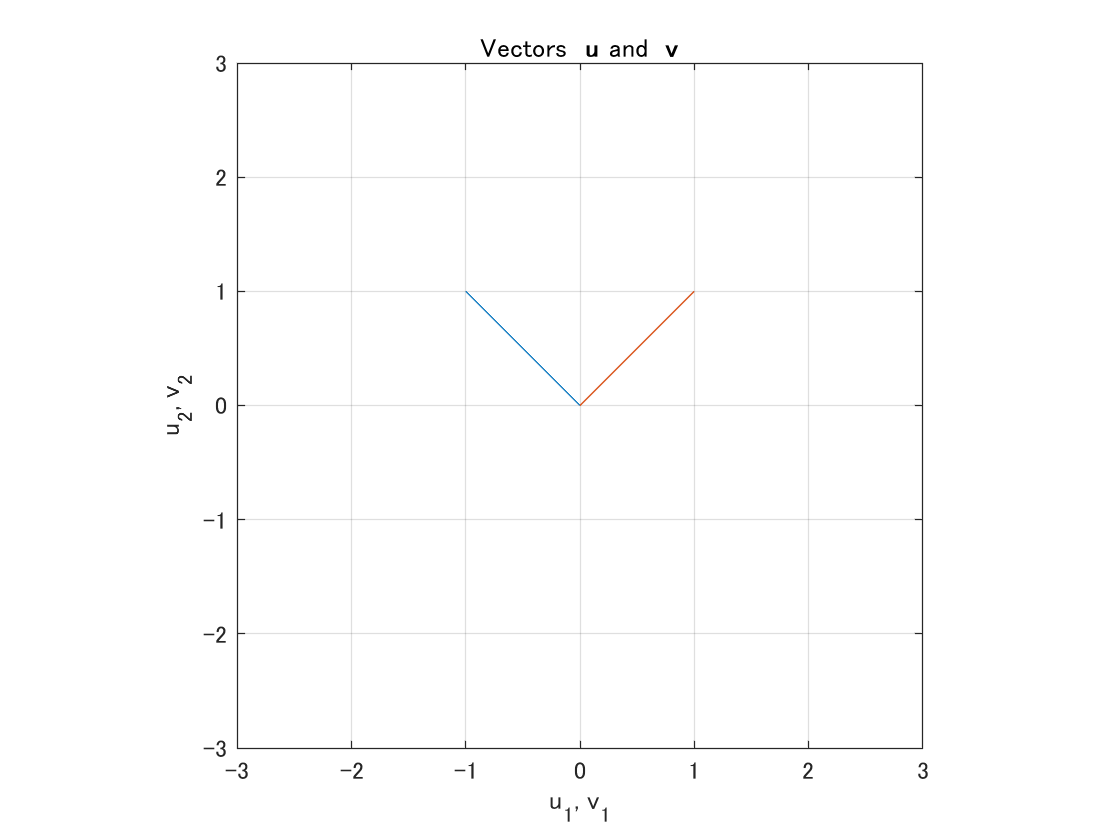

% Plot vector v with the contour plot of lp-norm
plotv([u v],'-')
title('Vectors {\bf u} and {\bf v}')
xlabel('u_1, v_1')
ylabel('u_2, v_2')
colormap('default')
axis equal
axis([-3 3 -3 3])
grid on

### ベクトルとしてみた$N_1 \times N_2$配列の 内積

(Inner product of $N_1 \times N_2$ arrays as vector)


$$\langle\mathbf{u},\mathbf{v}\rangle=\sum_{j=0}^{N_2-1}\sum_{i=0}^{N_1-1}u_{i,j}v_{i,j}$$


ただし， $u_{i,j}, v_{i,j}$はベクトル $\mathbf{u}, \mathbf{v}\in\mathbb{R}^{N_1\times N_2}$ の $i,j$-番目要素 $[\mathbf{u}]_{i,j},[\mathbf{v}]_{i,j}$。

( where $u_{i,j}, v_{i,j}$ are the $i,j$-th element of vector $\mathbf{u}, \mathbf{v}\in\mathbb{R}^{N}$ , i.e.,  $[\mathbf{u}]_{i,j},[\mathbf{v}]_{i,j}$, respectively.)

% Array dimension
ndim1 = 2;
ndim2 = 2;
% Generate a N1xN2 arrya v with normally distributed random numbers
u = randn(ndim1,ndim2)

u =    -1.5771    0.2820
    0.5080    0.0335


v = randn(ndim1,ndim2)

v =    -1.3337    0.3502
    1.1275   -0.2991


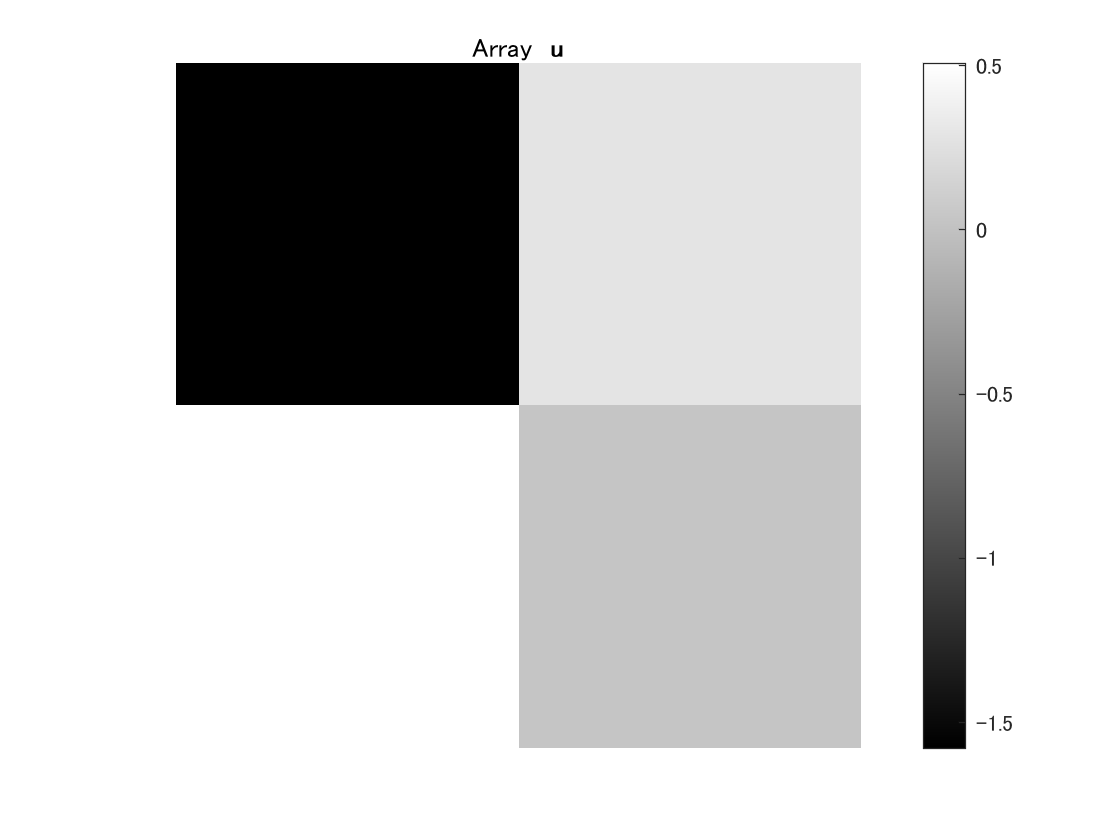

% Visualization of array u
imagesc(u)
title('Array {\bf u}')
colormap('gray')
colorbar
axis equal
axis off

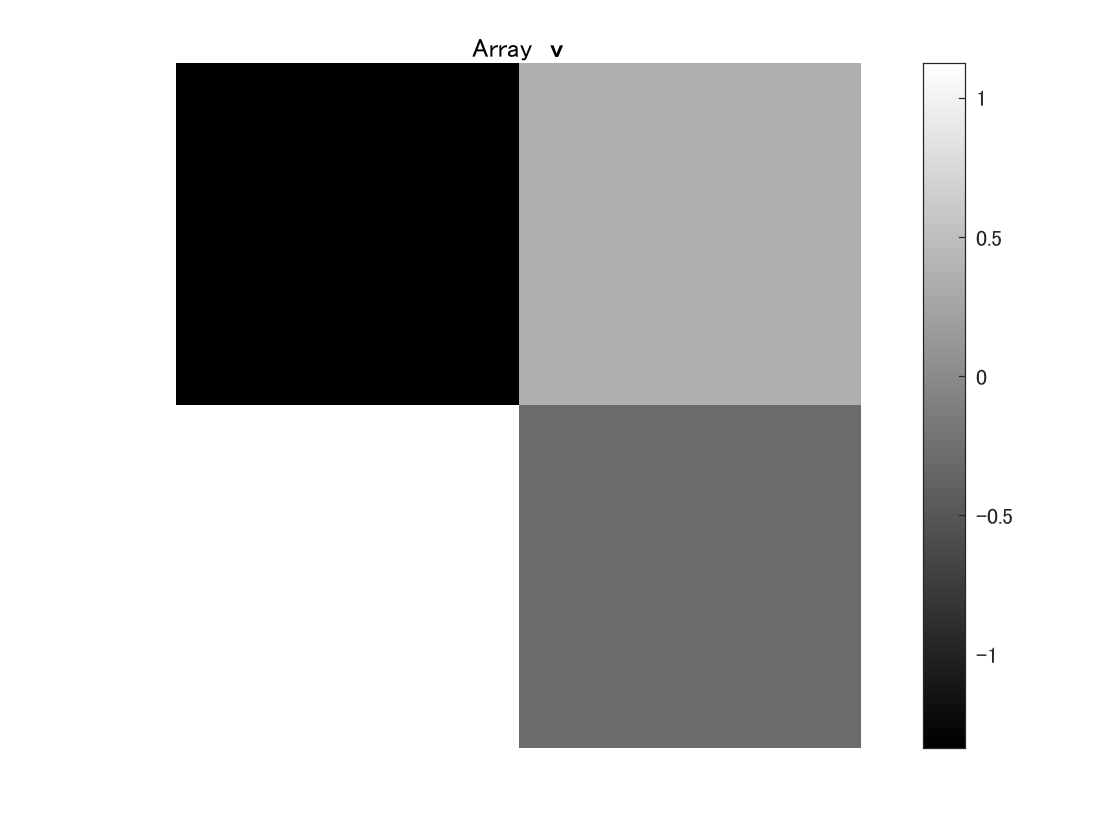

% Visualization of array v
imagesc(v)
title('Array {\bf v}')
colormap('gray')
colorbar
axis equal
axis off

% Inner product of arrays u and v as vectors
innerprod = dot(u(:),v(:));
disp(['<u,v> = ' num2str(innerprod)])

<u,v> = 2.7648


### $N$次元ベクトルの $\ell_p$-ノルム

($\ell_p$-norm of a $N$-dimensional vector)


$$\|\mathbf{v}\|_{p}=\left(\sum_{i=0}^{N-1}\left|v_{i}\right|^{p}\right)^{\frac{1}{p}}$$


ただし， $v_i$はベクトル $\mathbf{v}\in\mathbb{R}^{N}$ の $i$-番目要素 $[\mathbf{v}]_i$。

(where $v_i$ stands for the $i$-th element of vector $\mathbf{v}\in\mathbb{R}^{N}$ , i.e.,  $[\mathbf{v}]_i$.)

% Generate an two-dimensional vector v 
v1 = 1;
v2 = 1;
v = [v1, v2].'

v =      1
     1


% Setting of parameter p
p = 1;

% lp-norm of v
lpnorm = norm(v,p);
disp(['||v||_' num2str(p) ' = ' num2str(lpnorm)])

||v||_1 = 2


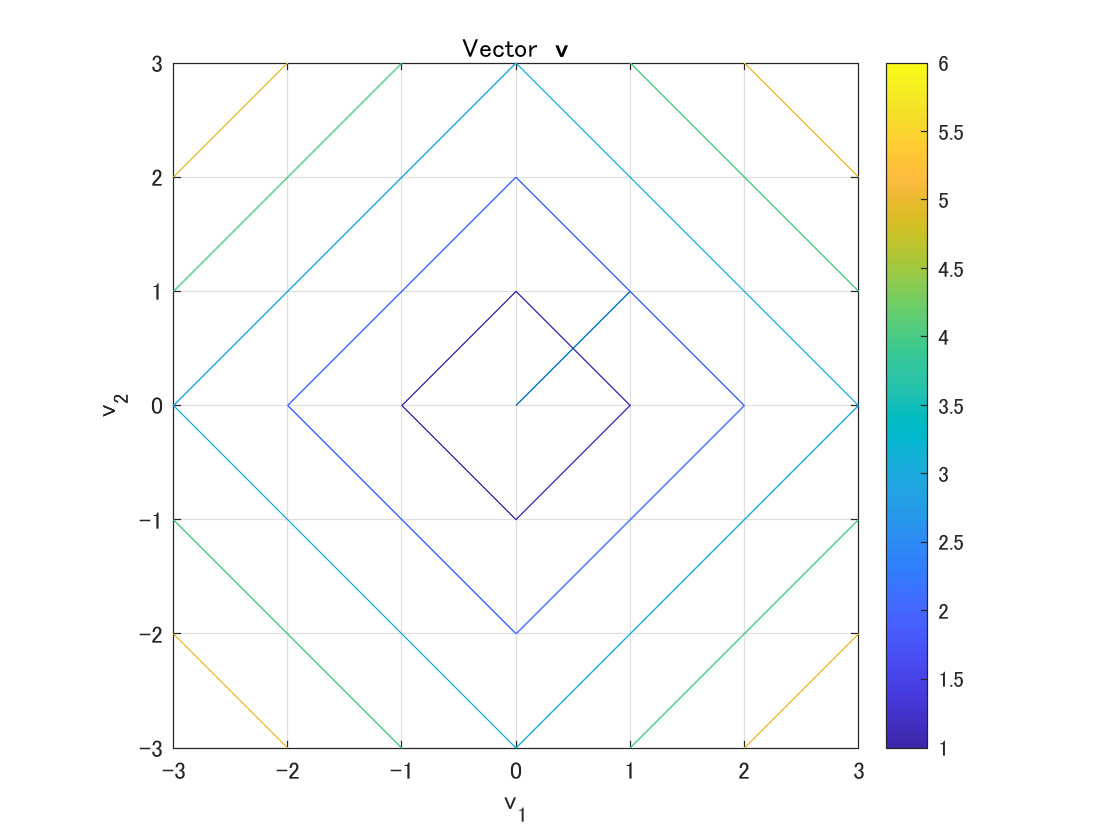

% Plot vector v with the contour plot of lp-norm
plotv(v,'-')
title('Vector {\bf v}')
xlabel('v_1')
ylabel('v_2')
colormap('default')
axis equal
axis([-3 3 -3 3])
grid on
hold on
% Contour plot of lp-norm
fcontour(@(v1,v2) vecnorm([v1(:) v2(:)].',p),[-3 3 -3 3])
colorbar
hold off

### ベクトルとしてみた$N_1 \times N_2$配列の $\ell_p$-ノルム

($\ell_p$-norm of a $N_1 \times N_2$ array as a vector)


$$\|\mathbf{v}\|_{p}=\left(\sum_{j=0}^{N_2-1}\sum_{i=0}^{N_1-1}\left|v_{i,j}\right|^{p}\right)^{\frac{1}{p}}$$


ただし， $v_{i,j}$はベクトルとしてみた配列 $\mathbf{v}\in\mathbb{R}^{N_1\times N_2}$ の $i,j$-番目要素 $[\mathbf{v}]_{i,j}$。

(where $v_{i,j}$ stands for the $i,j$-th element of array $\mathbf{v}$ as a vector, i.e.,  $[\mathbf{v}]_{i,j}$.)

% Array dimension
ndim1 = 2;
ndim2 = 2;
% Generate a N1xN2 arrya v with normally distributed random numbers
v = randn(ndim1,ndim2)

v =     0.0229   -1.7502
   -0.2620   -0.2857


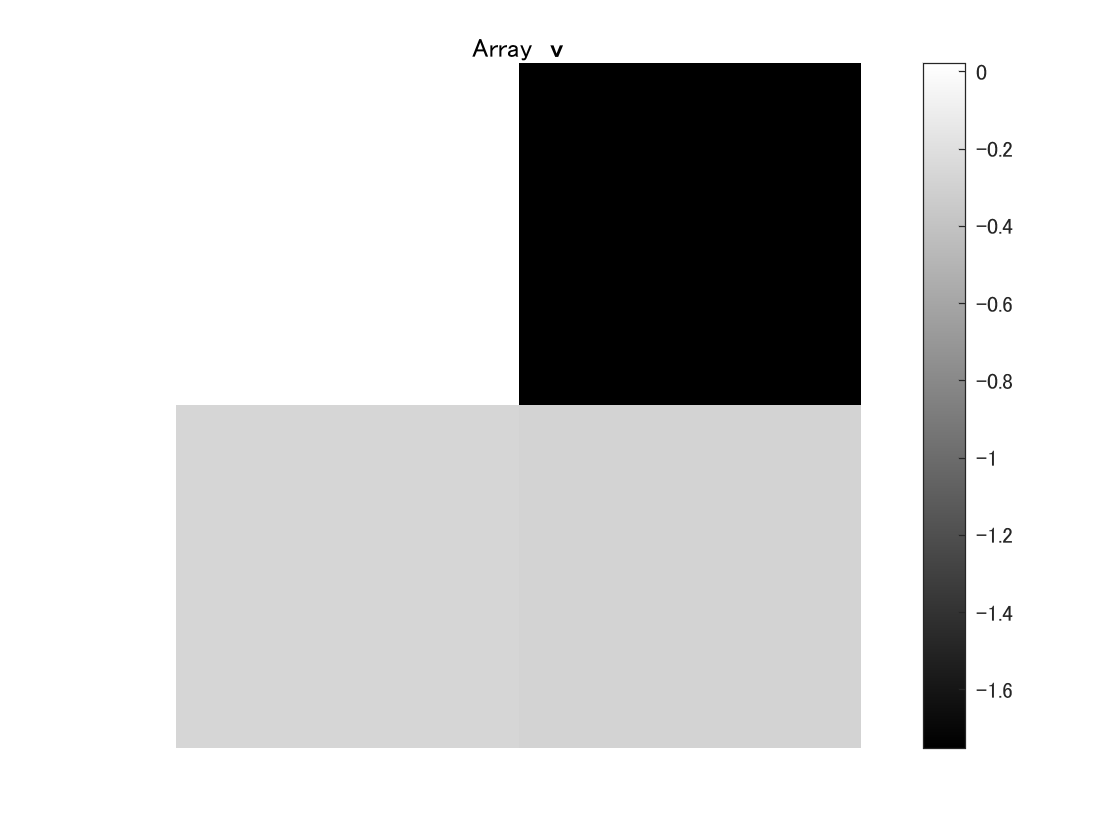

% Visualization of array v
imagesc(v)
title('Array {\bf v}')
colormap('gray')
colorbar
axis equal
axis off

% Setting of parameter p
p = 1;

% lp-(element-wise) norm of v
lpnorm = norm(v(:),p);
disp(['||v||_' num2str(p) ' = ' num2str(lpnorm)])

||v||_1 = 2.3207


© Copyright, Shogo MURAMATSU, All rights reserved.